# Camille Rakotoranto, April 2025, MATLAB R2024b, The MathWorks Inc., Natick, MA, USA

# FOOOF Implementation

This script allows for the implementation of FOOOF to the data files created using scripts: "PreProcessing_RestingState" and "PreProcessing_AlphaBlock". For adequate functioning, the script requires sequential execution from Section 1 to 7.

**Note: Prior to using this script, the parameters for the FOOOF algorithm need to be tuned using the FOOOF_tuning.mlx script.**

- Section 1: Compuatation of Individual PSDs

- Section 2: Computation of Average PSDs

- Section 3: Graphical comparison of pre-FOOOF PSDs between the ear and scalp configurations

- Section 4: Implementation of FOOOF to the Resting State condition

- Section 5: Implementation of FOOOF to the Alpha Block conditions

- Section 6: Saving Results

- Section 7: Comparison of average pre- and post-FOOOF PSDs

## Section 1: Computation of Power Spectral Densities

This section computes the PSD for the Resting State and the two conditions obtained from the Alpha Block: Eyes Closed and Eyes Open. It does so for all participants and all configurations. Results are stored in a struct, to be used in the subsequent Sections. 

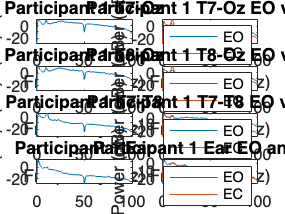

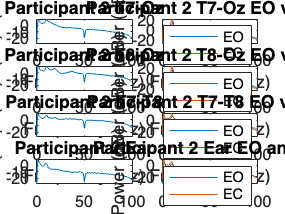

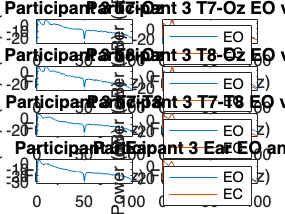

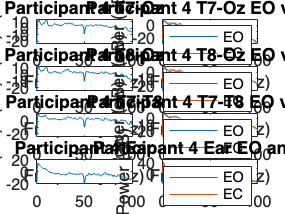

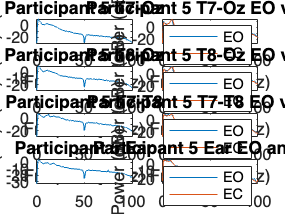

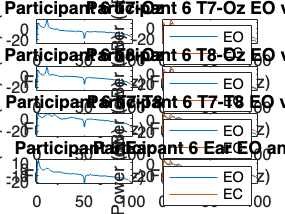

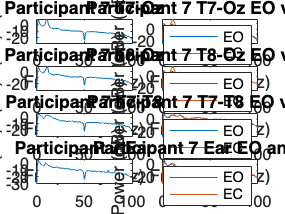

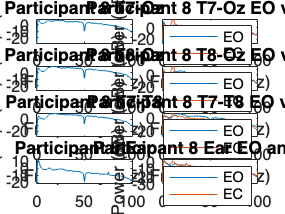

% Definition of arrays for PSD data for channels and participants
% Resting State 
psd_T7_all_participants = [];
psd_T8_all_participants = [];
psd_T7T8_all_participants = [];
psd_ear_all_participants = [];
f_T7_all_participants = [];
f_T8_all_participants = [];
f_T7T8_all_participants = [];
f_ear_all_participants = [];

% Eyes Closed and Eyes Open
psd_T7ec_all_participants = [];
psd_T7eo_all_participants = [];
psd_T8ec_all_participants = [];
psd_T8eo_all_participants = [];
psd_T7T8ec_all_participants = [];
psd_T7T8eo_all_participants = [];
psd_ear_ec_all_participants = [];
psd_ear_eo_all_participants = [];

f_T7ec_all_participants = []; 
f_T7eo_all_participants = []; 
f_T8ec_all_participants = []; 
f_T8eo_all_participants = [];
f_T7T8ec_all_participants = []; 
f_T7T8eo_all_participants = [];
f_ear_ec_all_participants = [];
f_ear_eo_all_participants = [];

% Definition of structs to store the results
original_results = struct();
fooof_results = struct();
fooof_avg_results = struct();

% Sampling Frequency and Parameters for pwelch
Fs = 250;                           % Sampling frequency (Hz)
window_length = 2 * Fs;             % Window length of 2 seconds
nfft = 2^nextpow2(window_length);   % Use the next power of 2 for NFFT
noverlap = window_length / 2;       % 50% overlap

n_participants = 15;

% Loop through each participant
for participant = 1:n_participants

    %% Computation of PSDs for the T7-Oz and T8-Oz configurations
    % Store the Resting State data
    filename = sprintf('Participant_%d_T7andT8_refPOz_RS.mat', participant);
    loaded_data = load(filename);

    % Extract the data for T7 and T8 
    data_T7 = loaded_data.participant_data.channel_T7; 
    data_T8 = loaded_data.participant_data.channel_T8; 

    % Compute the PSD
    [psd_T7, f_T7] = pwelch(data_T7, window_length, noverlap, nfft, Fs); 
    [psd_T8, f_T8] = pwelch(data_T8, window_length, noverlap, nfft, Fs); 
  
    % Store the PSDs of participant in arrays
    psd_T7_all_participants = [psd_T7_all_participants, psd_T7];
    psd_T8_all_participants = [psd_T8_all_participants, psd_T8];

    f_T7_all_participants = [f_T7_all_participants, f_T7];
    f_T8_all_participants = [f_T8_all_participants, f_T8];


    % Store the data for Alpha Block
    filename = sprintf('Participant_%d_T7andT8_refPOz_AB.mat', participant);
    loaded_data = load(filename);
    
    % Extract the data for T7 and T8 for EC and EO
    data_T7_ec = loaded_data.participant_data.channel_T7ec; 
    data_T7_eo = loaded_data.participant_data.channel_T7eo; 
    data_T8_ec = loaded_data.participant_data.channel_T8ec; 
    data_T8_eo = loaded_data.participant_data.channel_T8eo;
    
    % Compute the PSD
    [psd_T7_ec, f_T7ec] = pwelch(data_T7_ec, window_length, noverlap, nfft, Fs); 
    [psd_T7_eo, f_T7eo] = pwelch(data_T7_eo, window_length, noverlap, nfft, Fs); 
    [psd_T8_ec, f_T8ec] = pwelch(data_T8_ec, window_length, noverlap, nfft, Fs); 
    [psd_T8_eo, f_T8eo] = pwelch(data_T8_eo, window_length, noverlap, nfft, Fs);

    % Store the PSDs of participant in arrays
    psd_T7ec_all_participants = [psd_T7ec_all_participants, psd_T7_ec];
    psd_T7eo_all_participants = [psd_T7eo_all_participants, psd_T7_eo];
    psd_T8ec_all_participants = [psd_T8ec_all_participants, psd_T8_ec];
    psd_T8eo_all_participants = [psd_T8eo_all_participants, psd_T8_eo];

    f_T7ec_all_participants = [f_T7ec_all_participants, f_T7ec];
    f_T7eo_all_participants = [f_T7eo_all_participants, f_T7eo];
    f_T8ec_all_participants = [f_T8ec_all_participants, f_T8ec];
    f_T8eo_all_participants = [f_T8eo_all_participants, f_T8eo];


    %% Computation of PSDs for the T7-Oz and T8-Oz configurations
    % Store the data for Resting State
    filename = sprintf('Participant_%d_T7_refT8_RS.mat', participant);
    loaded_data = load(filename);

    % Extract the data for T7 
    data_T7T8 = loaded_data.participant_data.channel_T7; % or 'T7_data'

    % Compute the PSD
    [psd_T7T8, f_T7T8] = pwelch(data_T7T8, window_length, noverlap, nfft, Fs); % Power spectrum of T7
    
    % Store the PSD of participant in arrays
    psd_T7T8_all_participants = [psd_T7T8_all_participants, psd_T7T8];

    f_T7T8_all_participants = [f_T7T8_all_participants, f_T7T8];

    % Store the data for Alpha Block
    filename = sprintf('Participant_%d_T7_refT8_AB.mat', participant);
    loaded_data = load(filename);
    
    % Extract the data for T7 for EC and EO
    data_T7T8_ec = loaded_data.participant_data.channel_T7ec; 
    data_T7T8_eo = loaded_data.participant_data.channel_T7eo; 

    % Compute the PSD
    [psd_T7T8_ec, f_T7T8ec] = pwelch(data_T7T8_ec, window_length, noverlap, nfft, Fs); 
    [psd_T7T8_eo, f_T7T8eo] = pwelch(data_T7T8_eo, window_length, noverlap, nfft, Fs); 

    % Store the PSDs of participant in arrays
    psd_T7T8ec_all_participants = [psd_T7T8ec_all_participants, psd_T7T8_ec];
    psd_T7T8eo_all_participants = [psd_T7T8eo_all_participants, psd_T7T8_eo];

    f_T7T8ec_all_participants = [f_T7T8ec_all_participants, f_T7T8ec];
    f_T7T8eo_all_participants = [f_T7T8eo_all_participants, f_T7T8eo];


    %% Computation of PSDs for ear
    % Store the data for Resting State
    filename = sprintf('Participant_%d_ear_RS.mat', participant);
    loaded_data = load(filename);

    % Extract data 
    data_ear = loaded_data.participant_data.ear; 

    % Compute the PSD
    [psd_ear, f_ear] = pwelch(data_ear, window_length, noverlap, nfft, Fs); % Power spectrum 
  
    % Store the PSD
    psd_ear_all_participants = [psd_ear_all_participants, psd_ear];
    f_ear_all_participants = [f_ear_all_participants, f_ear];

    % Store the data for Alpha Block
    filename = sprintf('Participant_%d_ear_AB.mat', participant);
    loaded_data = load(filename);
    
    % Extract  data for EC and EO
    data_ear_ec = loaded_data.participant_data.ear_ec; % Eyes-closed data
    data_ear_eo = loaded_data.participant_data.ear_eo; % Eyes-open data 
    
    % Compute the PSDs
    [psd_ear_ec, f_ear_ec] = pwelch(data_ear_ec, window_length, noverlap, nfft, Fs); 
    [psd_ear_eo, f_ear_eo] = pwelch(data_ear_eo, window_length, noverlap, nfft, Fs);
    
    % Store the PSDs
    psd_ear_ec_all_participants = [psd_ear_ec_all_participants, psd_ear_ec];
    psd_ear_eo_all_participants = [psd_ear_eo_all_participants, psd_ear_eo];
    f_ear_ec_all_participants = [f_ear_ec_all_participants, f_ear_ec];
    f_ear_eo_all_participants = [f_ear_eo_all_participants, f_ear_eo];

    

    %% Store pre-FOOOF PSDs for all configurations and participants
    % Resting State
    original_results(participant).T7.rs = data_T7;
    original_results(participant).T8.rs = data_T8;
    original_results(participant).T7T8.rs = data_T7T8;
    original_results(participant).ear.rs = data_ear;

    % Alpha Block: Eyes Open and Eyes Closed
    original_results(participant).T7.ec = data_T7_ec;
    original_results(participant).T7.eo = data_T7_eo;
    original_results(participant).T8.ec = data_T8_ec;
    original_results(participant).T8.eo = data_T8_eo;
    original_results(participant).T7T8.ec = data_T7T8_ec;
    original_results(participant).T7T8.eo = data_T7T8_eo;
    original_results(participant).ear.ec = data_ear_ec;
    original_results(participant).ear.eo = data_ear_eo;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%% Plot PSDs for each participant with power in dB
    figure;

    % T7-Oz configuration
    subplot(4,2,1);
    plot(f_T7, 10*log10(psd_T7)); 
    title(sprintf('Participant %d T7-Oz', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    xlim([0 100]);

    subplot(4,2,2);
    plot(f_T7eo, 10*log10(psd_T7_eo)); 
    hold on;
    plot(f_T7ec, 10*log10(psd_T7_ec)); 
    title(sprintf('Participant %d T7-Oz EO vs. EC', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    legend('EO', 'EC');
    xlim([0 100]);
   
    % T8-Oz configuration
    subplot(4,2,3);
    plot(f_T8, 10*log10(psd_T8)); 
    title(sprintf('Participant %d T8-Oz', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    xlim([0 100]);

    subplot(4,2,4);
    plot(f_T8eo, 10*log10(psd_T8_eo)); 
    hold on;
    plot(f_T8ec, 10*log10(psd_T8_ec)); 
    title(sprintf('Participant %d T8-Oz EO vs. EC', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    legend('EO', 'EC');
    xlim([0 100]);

    % T7-T8 configuration
    subplot(4,2,5);
    plot(f_T7T8, 10*log10(psd_T7T8)); 
    title(sprintf('Participant %d T7-T8', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    xlim([0 100]);

    subplot(4,2,6);
    plot(f_T7T8eo, 10*log10(psd_T7T8_eo)); 
    hold on;
    plot(f_T7T8ec, 10*log10(psd_T7T8_ec)); 
    title(sprintf('Participant %d T7-T8 EO vs. EC', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    legend('EO', 'EC');
    xlim([0 100]);

    % Ear configuration
    subplot(4,2,7);
    plot(f_ear, 10*log10(psd_ear)); 
    title(sprintf('Participant %d Ear', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    xlim([0 100]);

    subplot(4,2,8);
    plot(f_ear_eo, 10*log10(psd_ear_eo)); 
    hold on;
    plot(f_ear_ec,10*log10(psd_ear_ec)); 
    title(sprintf('Participant %d Ear EO and EC', participant));
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    xlim([0 100]);
    legend('EO','EC');

end

## Section 2: Computation of Average Power Spectral Densities 

This section takes the average across all participants for each configuration and each condition to obtain average PSDs. It displays 4 Figures which each consist of the three conditions superimposed on to one graph for each configuation.

% Average of the PSDs for every configurations and condition
%% Resting State
avg_psd_T7 = mean(psd_T7_all_participants, 2);
avg_psd_T8 = mean(psd_T8_all_participants, 2);
avg_psd_T7T8 = mean(psd_T7T8_all_participants, 2);
avg_psd_ear = mean(psd_ear_all_participants, 2);

avg_f_T7 = mean(f_T7_all_participants, 2);
avg_f_T8 = mean(f_T8_all_participants, 2);
avg_f_T7T8 = mean(f_T7T8_all_participants, 2);
avg_f_ear = mean(f_ear_all_participants, 2);

% Convert to dB (log scale, 10 * log10(Power))
avg_psd_T7_dB = 10 * log10(avg_psd_T7);
avg_psd_T8_dB = 10 * log10(avg_psd_T8);
avg_psd_T7T8_dB = 10 * log10(avg_psd_T7T8);
avg_psd_ear_dB = 10 * log10(avg_psd_ear);

%% Alpha Block
avg_psd_T7_ec = mean(psd_T7ec_all_participants, 2);
avg_psd_T7_eo = mean(psd_T7eo_all_participants, 2);
avg_psd_T8_ec = mean(psd_T8ec_all_participants, 2);
avg_psd_T8_eo = mean(psd_T8eo_all_participants, 2);
avg_psd_T7T8_ec = mean(psd_T7T8ec_all_participants, 2);
avg_psd_T7T8_eo = mean(psd_T7T8eo_all_participants, 2);
avg_psd_ear_ec = mean(psd_ear_ec_all_participants, 2);
avg_f_ear_ec = mean(f_ear_ec_all_participants, 2);

avg_f_T7ec = mean(f_T7ec_all_participants, 2);
avg_f_T7eo = mean(f_T7eo_all_participants, 2);
avg_f_T8ec = mean(f_T8ec_all_participants, 2);
avg_f_T8eo = mean(f_T8eo_all_participants, 2);
avg_f_T7T8ec = mean(f_T7T8ec_all_participants, 2);
avg_f_T7T8eo = mean(f_T7T8eo_all_participants, 2);
avg_psd_ear_eo = mean(psd_ear_eo_all_participants, 2);
avg_f_ear_eo = mean(f_ear_eo_all_participants, 2);

% Plot Average PSDs
figure;
hold on;
plot(avg_f_T7, avg_psd_T7_dB);
plot(avg_f_T7eo, 10*log10(avg_psd_T7_eo));
plot(avg_f_T7ec, 10*log10(avg_psd_T7_ec));
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Resting State', 'Eyes Open', 'Eyes Closed', 'FontSize', 14);
set(gca, 'FontSize', 15);  
xlim([0 100]);
% Save the image 
print('Average_T7Oz_Paradigms_Power_Frequency.tif', '-dtiff', '-r600');

figure;
hold on;
plot(avg_f_T8, avg_psd_T8_dB);
plot(avg_f_T8eo, 10*log10(avg_psd_T8_eo));
plot(avg_f_T8ec, 10*log10(avg_psd_T8_ec));
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Resting State', 'Eyes Open', 'Eyes Closed', 'FontSize', 14);
set(gca, 'FontSize', 15); 
xlim([0 100]);
% Save the image 
print('Average_T8Oz_Paradigms_Power_Frequency.tif', '-dtiff', '-r600');

figure;
hold on;
plot(avg_f_T7T8, avg_psd_T7T8_dB);
plot(avg_f_T7T8eo, 10*log10(avg_psd_T7T8_eo));
plot(avg_f_T7T8ec, 10*log10(avg_psd_T7T8_ec));
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Resting State', 'Eyes Open', 'Eyes Closed', 'FontSize', 14);
set(gca, 'FontSize', 15); 
xlim([0 100]);
% Save the image 
print('Average_T7T8_Paradigms_Power_Frequency.tif', '-dtiff', '-r600');

figure;
hold on;
plot(avg_f_ear, avg_psd_ear_dB);
plot(avg_f_ear_eo, 10*log10(avg_psd_ear_eo));
plot(avg_f_ear_ec, 10*log10(avg_psd_ear_ec));
xlabel('Frequency (Hz)');
ylabel('Power (dB)');
legend('Resting State', 'Eyes Open', 'Eyes Closed', 'FontSize', 14);
set(gca, 'FontSize', 15); 
xlim([0 100]);
% Save the image 
print('Average_Ear_Paradigms_Power_Frequency.tif', '-dtiff', '-r600');



## Section 3: Comparison of pre-FOOOF PSDs between the ear and scalp configurations

This section provides a graphical comparison, including significant difference, between the ear and every scalp configuration's pre-FOOOF PSDs for the three conditions. 

% Definition of arrays for conditions and configurations
conditions = {'rs', 'ec', 'eo'}; 
configurations = {'T7', 'T8', 'T7T8'}; 

% Definition of Alpha Band range
alpha_band = [8, 12]; 

% Definition of stuct to store the p values obtained from the comparison.
% These are used for plotting of the PSDs for visual representation of any
% significant difference
p_values = struct();

% Loop through every condition
for cond = conditions
    % Define the condition analysed
    cond = cond{1}; 
    
    % Loop through every configuration 
    for config = configurations
        % Define the configuration analysed
        config = config{1}; 
        
        % Initialise arrays to store the peak alpha power value for the ear
        % and respective scalp configuration
        peak_alpha_ear = [];
        peak_alpha_config = [];
        
        % Loop through evey participant
        for participant = 1:n_participants
            % Extract the PSDs for ear and scalp configuration given the condition being analysed
            switch cond
                case 'rs'
                    f_ear = f_ear_all_participants(:,participant);
                    psd_ear = psd_ear_all_participants(:,participant);
                    switch config
                        case 'T7'
                            f_config = f_T7_all_participants(:,participant);
                            psd_config = psd_T7_all_participants(:,participant);
                        case 'T8'
                            f_config = f_T8_all_participants(:,participant);
                            psd_config = psd_T8_all_participants(:,participant);
                        case 'T7T8'
                            f_config = f_T7T8_all_participants(:,participant);
                            psd_config = psd_T7T8_all_participants(:,participant);
                    end
                case 'ec'
                    f_ear = f_ear_ec_all_participants(:,participant);
                    psd_ear = psd_ear_ec_all_participants(:,participant);
                    switch config
                        case 'T7'
                            f_config = f_T7ec_all_participants(:,participant);
                            psd_config = psd_T7ec_all_participants(:,participant);
                        case 'T8'
                            f_config = f_T8ec_all_participants(:,participant);
                            psd_config = psd_T8ec_all_participants(:,participant);
                        case 'T7T8'
                            f_config = f_T7T8ec_all_participants(:,participant);
                            psd_config = psd_T7T8ec_all_participants(:,participant);
                    end
                case 'eo'
                    f_ear = f_ear_eo_all_participants(:,participant);
                    psd_ear = psd_ear_eo_all_participants(:,participant);
                    switch config
                        case 'T7'
                            f_config = f_T7eo_all_participants(:,participant);
                            psd_config = psd_T7eo_all_participants(:,participant);
                        case 'T8'
                            f_config = f_T8eo_all_participants(:,participant);
                            psd_config = psd_T8eo_all_participants(:,participant);
                        case 'T7T8'
                            f_config = f_T7T8eo_all_participants(:,participant);
                            psd_config = psd_T7T8eo_all_participants(:,participant);
                    end
            end
            
            % Compute the peak alpha power for both
            alpha_idx_ear = f_ear >= alpha_band(1) & f_ear <= alpha_band(2);
            alpha_idx_config = f_config >= alpha_band(1) & f_config <= alpha_band(2);
            
            peak_alpha_ear = [peak_alpha_ear; max(psd_ear(alpha_idx_ear))];
            peak_alpha_config = [peak_alpha_config; max(psd_config(alpha_idx_config))];
        end

        % Assess the normality of the sets
        [h_x, p_ear] = swtest(peak_alpha_ear); 
        [h_y, p_config] = swtest(peak_alpha_config); 
        
        % Perform paired t-test or Wilcoxon based on normality
        if h_x == 0 && h_y == 0 
            [h, p, ci, stats] = ttest(peak_alpha_ear, peak_alpha_config);
            test_type = 'Paired t-test';
        else 
            [p, ~] = signrank(peak_alpha_ear, peak_alpha_config);
            test_type = 'Wilcoxon signed-rank test';
        end
        
        % Store p-value
        p_values.(cond).(config) = p;
        
        % Plot the PSDs of the ear and scalp configuration on the same
        % graph with an emphasis on the alpha band.
        % If there is a significant difference between the peak alpha power
        % of the ear and the scalp then display this on the graph usign the
        % p-value.
        figure;
        hold on;
        alpha_x = [alpha_band(1) alpha_band(2) alpha_band(2) alpha_band(1)]; % X-coordinates for the rectangle
        alpha_y = [-15, -15, 20, 20]; % Y-coordinates for the rectangle
        fill(alpha_x, alpha_y, [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'DisplayName', 'Alpha Band'); % Light red shading

        % Plot the PSD for the ear given the condition
        switch cond
            case 'rs'
                plot(avg_f_ear, avg_psd_ear_dB, 'DisplayName', 'Ear (Resting State)');
            case 'ec'
                plot(avg_f_ear_ec, 10*log10(avg_psd_ear_ec), 'DisplayName', 'Ear (Eyes Closed)');
            case 'eo'
                plot(avg_f_ear_eo, 10*log10(avg_psd_ear_eo), 'DisplayName', 'Ear (Eyes Open)');
        end
        
        % Plot the scalp configuration PSD given the condition
        switch cond
            case 'rs'
                switch config
                    case 'T7'
                        plot(avg_f_T7, avg_psd_T7_dB, 'DisplayName', 'T7 (Resting State)');
                    case 'T8'
                        plot(avg_f_T8, avg_psd_T8_dB, 'DisplayName', 'T8 (Resting State)');
                    case 'T7T8'
                        plot(avg_f_T7T8, avg_psd_T7T8_dB, 'DisplayName', 'T7-T8 (Resting State)');
                end
            case 'ec'
                switch config
                    case 'T7'
                        plot(avg_f_T7ec, 10*log10(avg_psd_T7_ec), 'DisplayName', 'T7 (Eyes Closed)');
                    case 'T8'
                        plot(avg_f_T8ec, 10*log10(avg_psd_T8_ec), 'DisplayName', 'T8 (Eyes Closed)');
                    case 'T7T8'
                        plot(avg_f_T7T8ec, 10*log10(avg_psd_T7T8_ec), 'DisplayName', 'T7-T8 (Eyes Closed)');
                end
            case 'eo'
                switch config
                    case 'T7'
                        plot(avg_f_T7eo, 10*log10(avg_psd_T7_eo), 'DisplayName', 'T7 (Eyes Open)');
                    case 'T8'
                        plot(avg_f_T8eo, 10*log10(avg_psd_T8_eo), 'DisplayName', 'T8 (Eyes Open)');
                    case 'T7T8'
                        plot(avg_f_T7T8eo, 10*log10(avg_psd_T7T8_eo), 'DisplayName', 'T7-T8 (Eyes Open)');
                end
        end
        
        % Add asterisks onto the figure if significant difference between
        % the two
        if p < 0.0001
            asterisks = '****';
        elseif p < 0.001
            asterisks = '***';
        elseif p < 0.01
            asterisks = '**';
        elseif p < 0.05
            asterisks = '*';
        else
            asterisks = '';
        end
        
        % Place the asterisks above the peaks
        if ~isempty(asterisks)
            text(mean(alpha_band), max([avg_psd_ear_dB(alpha_idx_ear); avg_psd_T7_dB(alpha_idx_config)]) + 1, asterisks, ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 18, ...
                'Color', 'black');
        end
        
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        set(gca, 'FontSize', 15);  
        legend show;
        xlim([5 30]);
        % Save the figure
        print(['Average_Ear_vs_' config '_' cond '.tif'], '-dtiff', '-r600');
    end
end

## Section 4: Implementation of FOOOF to the Resting State condition

This section implements FOOOF to the Resting State PSDs for individual participants and the average.

% Define the settings of the algorithm based on the parameters obtained for tuning using FOOOF_tuning.mlx script.
settings = struct();
% set the range
f_range = [2, 100];
settings = fooof_check_settings(settings);
% Adjust the parameter values
settings.peak_width_limits = [1.1, 7];  
settings.max_n_peaks = 11;
settings.min_peak_height = 0.05;
settings.peak_threshold = 1.5;
settings.verbose = false; 

% Initialize arrays to store the FOOOF result. Note this code checks
% whether using an aperiodic knee yields a better fit. Thus, it compares
% models with and without a knee and maintains the best fit, which is
% stored in these arrays.
best_results_T7_all_participants = [];
best_results_T8_all_participants = [];
best_results_T7T8_all_participants = [];
best_results_ear_all_participants = [];
best_results_T7_avg = [];
best_results_T8_avg = [];
best_results_T7T8_avg = [];
best_results_ear_avg = [];

% Initialise arrays to store the averages
avg_psd_ear = [];
avg_f_ear = [];
avg_psd_T7 = [];
avg_f_T7 = [];
avg_psd_T8 = [];
avg_f_T8 = [];
avg_psd_T7T8 = [];
avg_f_T7T8 = [];

% Loop through each participant
for participant = 1:n_participants

    % Extract PSD for participant
    psd_T7 = psd_T7_all_participants(:, participant);
    f_T7 = f_T7_all_participants(:, participant);
    
    psd_T8 = psd_T8_all_participants(:, participant);
    f_T8 = f_T8_all_participants(:, participant);

    psd_T7T8 = psd_T7T8_all_participants(:, participant);
    f_T7T8 = f_T7T8_all_participants(:, participant);

    psd_ear = psd_ear_all_participants(:, participant);
    f_ear = f_ear_all_participants(:, participant);

    % Store the PSD of participant in arrays which will be used to compute the
    % average FOOOF models
    avg_psd_ear(:, participant) = psd_ear;
    avg_f_ear(:,participant) = f_ear;

    avg_psd_T7(:, participant) = psd_T7;
    avg_f_T7(:,participant) = f_T7;

    avg_psd_T8(:, participant) = psd_T8;
    avg_f_T8(:,participant) = f_T8;

    avg_psd_T7T8(:, participant) = psd_T7T8;
    avg_f_T7T8(:,participant) = f_T7T8;

    %% Apply FOOOF to T7-Oz configuration

    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T7 = fooof(f_T7, psd_T7, f_range, settings, true);

    % Check 'knee' aperiodic mode
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T7 = fooof(f_T7, psd_T7, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_T7 = fooof_results_fixed_T7.r_squared;
    r_squared_knee_T7 = fooof_results_knee_T7.r_squared;

    % Compare R-squared values for T7 and pick the best fit
    if r_squared_fixed_T7 > r_squared_knee_T7
        disp(['Participant ' num2str(participant) ': The fixed aperiodic model has the higher R-squared value for T7-Oz.']);
        best_results_T7 = fooof_results_fixed_T7;
        best_results_T7 = fooof_db(best_results_T7);
    else
        disp(['Participant ' num2str(participant) ': The knee aperiodic model has the higher R-squared value for T7-Oz.']);
        best_results_T7 = fooof_results_knee_T7;
        best_results_T7 = fooof_db(best_results_T7);
    end

    %% Apply FOOOF to T8-Oz configuration
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T8 = fooof(f_T8, psd_T8, f_range, settings, true);

    % Check 'knee' aperiodic mode
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T8 = fooof(f_T8, psd_T8, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_T8 = fooof_results_fixed_T8.r_squared;
    r_squared_knee_T8 = fooof_results_knee_T8.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_T8 > r_squared_knee_T8
        disp(['Participant ' num2str(participant) ': The fixed aperiodic model has the higher R-squared value for T8-Oz.']);
        best_results_T8 = fooof_results_fixed_T8;
        best_results_T8 = fooof_db(best_results_T8);
    else
        disp(['Participant ' num2str(participant) ': The knee aperiodic model has the higher R-squared value for T8-Oz.']);
        best_results_T8 = fooof_results_knee_T8;
        best_results_T8 = fooof_db(best_results_T8);
    end


    %% Apply FOOOF to T7-T8 configuration
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T7T8 = fooof(f_T7T8, psd_T7T8, f_range, settings, true);

    % Check 'knee' aperiodic mode
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T7T8 = fooof(f_T7T8, psd_T7T8, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_T7T8 = fooof_results_fixed_T7T8.r_squared;
    r_squared_knee_T7T8 = fooof_results_knee_T7T8.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_T7T8 > r_squared_knee_T7T8
        disp(['Participant ' num2str(participant) ': The fixed aperiodic model has the higher R-squared value for T7-T8.']);
        best_results_T7T8 = fooof_results_fixed_T7T8;
        best_results_T7T8 = fooof_db(best_results_T7T8);
    else
        disp(['Participant ' num2str(participant) ': The knee aperiodic model has the higher R-squared value for T7-T8.']);
        best_results_T7T8 = fooof_results_knee_T7T8;
        best_results_T7T8 = fooof_db(best_results_T7T8);
    end

    %% Apply FOOOF to the ear
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_ear = fooof(f_ear, psd_ear, f_range, settings, true);

    % Check 'knee' aperiodic mode
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_ear = fooof(f_ear, psd_ear, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_ear = fooof_results_fixed_ear.r_squared;
    r_squared_knee_ear = fooof_results_knee_ear.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_ear > r_squared_knee_ear
        disp(['Participant ' num2str(participant) ': The fixed aperiodic model has the higher R-squared value for Ear.']);
        best_results_ear = fooof_results_fixed_ear;
        best_results_ear = fooof_db(best_results_ear);
    else
        disp(['Participant ' num2str(participant) ': The knee aperiodic model has the higher R-squared value for Ear.']);
        best_results_ear = fooof_results_knee_ear;
        best_results_ear = fooof_db(best_results_ear);
    end

    % Plot the FOOOF results for each participant and every configuration. This
    % provides graphs with the original spectrum, the FOOOF-reconstructed model fit and
    % the aperiodic fit.
    fooof_plot(best_results_T7);
    title(['T7-Oz - Participant ' num2str(participant)]);   
    fooof_plot(best_results_T8);
    title(['T8-Oz - Participant ' num2str(participant)]);
    fooof_plot(best_results_T7T8);
    title(['T7-T8 - Participant ' num2str(participant)]);
    fooof_plot(best_results_ear);
    title(['Ear - Participant ' num2str(participant)]);
    
    % Store FOOOOF results for this participant
    fooof_results(participant).T7.rs = best_results_T7;
    fooof_results(participant).T8.rs = best_results_T8;
    fooof_results(participant).T7T8.rs = best_results_T7T8;
    fooof_results(participant).ear.rs = best_results_ear;

end

% Find the mean PSDs for all participants
avg_psd_ear = mean(avg_psd_ear, 2, 'omitnan'); 
avg_f_ear = mean(avg_f_ear, 2, 'omitnan'); 
avg_psd_T7 = mean(avg_psd_T7, 2, 'omitnan'); 
avg_f_T7 = mean(avg_f_T7, 2, 'omitnan'); 
avg_psd_T8 = mean(avg_psd_T8, 2, 'omitnan'); 
avg_f_T8 = mean(avg_f_T8, 2, 'omitnan'); 
avg_psd_T7T8 = mean(avg_psd_T7T8, 2, 'omitnan'); 
avg_f_T7T8 = mean(avg_f_T7T8, 2, 'omitnan'); 

%% Implement FOOOF to the average PSDs
    
    %% Apply FOOOF to T7-Oz configuration
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T7 = fooof(avg_f_T7, avg_psd_T7, f_range, settings, true);

    % Check the 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T7 = fooof(avg_f_T7, avg_psd_T7, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T7 = fooof_results_fixed_avg_T7.r_squared;
    r_squared_knee_avg_T7 = fooof_results_knee_avg_T7.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_T7 > r_squared_knee_avg_T7
        best_results_avg_T7 = fooof_results_fixed_avg_T7;
        best_results_avg_T7 = fooof_db(best_results_avg_T7);
    else
        best_results_avg_T7 = fooof_results_knee_avg_T7;
        best_results_avg_T7 = fooof_db(best_results_avg_T7);
    end

    %% Apply FOOOF to T8-Oz configuration
    % Check the 'fixed' aperiodic mode
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T8 = fooof(avg_f_T8, avg_psd_T8, f_range, settings, true);

    % Check the 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T8 = fooof(avg_f_T8, avg_psd_T8, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T8 = fooof_results_fixed_avg_T8.r_squared;
    r_squared_knee_avg_T8 = fooof_results_knee_avg_T8.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_T8 > r_squared_knee_avg_T8
        best_results_avg_T8 = fooof_results_fixed_avg_T8;
        best_results_avg_T8 = fooof_db(best_results_avg_T8);
    else
        best_results_avg_T8 = fooof_results_knee_avg_T8;
        best_results_avg_T8 = fooof_db(best_results_avg_T8);
    end


    %% Apply FOOOF to T7-T8 configuration
    % Check the 'fixed' aperiodic mode
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T7T8 = fooof(avg_f_T7T8, avg_psd_T7T8, f_range, settings, true);

    % Check the 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T7T8 = fooof(avg_f_T7T8, avg_psd_T7T8, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T7T8 = fooof_results_fixed_avg_T7T8.r_squared;
    r_squared_knee_avg_T7T8 = fooof_results_knee_avg_T7T8.r_squared;

    % Compare R-squared values and pick the best one
    if r_squared_fixed_avg_T7T8 > r_squared_knee_avg_T7T8
        best_results_avg_T7T8 = fooof_results_fixed_avg_T7T8;
        best_results_avg_T7T8 = fooof_db(best_results_avg_T7T8);
    else
        best_results_avg_T7T8 = fooof_results_knee_avg_T7T8;
        best_results_avg_T7T8 = fooof_db(best_results_avg_T7T8);
    end

    %%

    %% Apply FOOOF to the ear
    % Check the 'fixed' aperiodic mode
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_ear = fooof(avg_f_ear, avg_psd_ear, f_range, settings, true);

    % Check the 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_ear = fooof(avg_f_ear, avg_psd_ear, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_ear = fooof_results_fixed_avg_ear.r_squared;
    r_squared_knee_avg_ear = fooof_results_knee_avg_ear.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_ear > r_squared_knee_avg_ear
        best_results_avg_ear = fooof_results_fixed_avg_ear;
        best_results_avg_ear = fooof_db(best_results_avg_ear);
    else
        best_results_avg_ear = fooof_results_knee_avg_ear;
        best_results_avg_ear = fooof_db(best_results_avg_ear);
    end

    % Store the average FOOOF results 
    fooof_avg_results.T7.rs = best_results_avg_T7;
    fooof_avg_results.T8.rs = best_results_avg_T8;
    fooof_avg_results.T7T8.rs = best_results_avg_T7T8;
    fooof_avg_results.ear.rs = best_results_avg_ear;

    % Plot the FOOOF results 
    fooof_plot(best_results_avg_T7);
    title('T7-Oz - Average');   
    fooof_plot(best_results_avg_T8);
    title('T8-Oz - Average');
    fooof_plot(best_results_avg_T7T8);
    title('T7-T8 - Average');
    fooof_plot(best_results_avg_ear);
    title('Ear - Average');


## Section 5: Implementation of FOOOF to the Alpha Block conditions

This section implements FOOOF to the Alpha Block conditions (Eyes Closed and Eyes Open) PSDs for individual participants and the average.

% Define the settings of the algorithm based on the parameters obtained for tuning using FOOOF_tuning.mlx script.
settings = struct();
% set the range
f_range = [2, 100];
settings = fooof_check_settings(settings);
% Adjust the parameter values
settings.peak_width_limits = [1.1, 7];  
settings.max_n_peaks = 11;
settings.min_peak_height = 0.05;
settings.peak_threshold = 1.5;
settings.verbose = false; 

% Initialize arrays to store the FOOOF result. Note this code checks
% whether using an aperiodic knee yields a better fit. Thus, it compares
% models with and without a knee and maintains the best fit, which is
% stored in these arrays.
best_results_T7ec_all_participants = [];
best_results_T7eo_all_participants = [];
best_results_T8ec_all_participants = [];
best_results_T8eo_all_participants = [];
best_results_T7T8ec_all_participants = [];
best_results_T7T8eo_all_participants = [];
best_results_ear_ec_all_participants = [];
best_results_ear_eo_all_participants = [];

% Initialise arrays to store the averages
avg_psd_ear_ec = [];
avg_f_ear_ec = [];
avg_psd_ear_eo = [];
avg_f_ear_eo = [];

avg_psd_T7_ec = [];
avg_f_T7_ec = [];
avg_psd_T7_eo = [];
avg_f_T7_eo = [];

avg_psd_T8_ec = [];
avg_f_T8_ec = [];
avg_psd_T8_eo = [];
avg_f_T8_eo = [];

avg_psd_T7T8_ec = [];
avg_f_T7T8_ec = [];
avg_psd_T7T8_eo = [];
avg_f_T7T8_eo = [];

% Loop through participants
for participant = 1:n_participants

    % Extract PSD for participant for Eyes Closed and Eyes Open
    psd_T7_ec = psd_T7ec_all_participants(:, participant);
    f_T7_ec = f_T7ec_all_participants(:, participant);
    psd_T7_eo = psd_T7eo_all_participants(:, participant);
    f_T7_eo = f_T7eo_all_participants(:, participant);
    
    psd_T8_ec = psd_T8ec_all_participants(:, participant);
    f_T8_ec = f_T8ec_all_participants(:, participant);
    psd_T8_eo = psd_T8eo_all_participants(:, participant);
    f_T8_eo = f_T8eo_all_participants(:, participant);

    psd_T7T8_ec = psd_T7T8ec_all_participants(:, participant);
    f_T7T8_ec = f_T7T8ec_all_participants(:, participant);
    psd_T7T8_eo = psd_T7T8eo_all_participants(:, participant);
    f_T7T8_eo = f_T7T8eo_all_participants(:, participant);

    psd_ear_ec = psd_ear_ec_all_participants(:, participant);
    f_ear_ec = f_ear_ec_all_participants(:, participant);
    psd_ear_eo = psd_ear_eo_all_participants(:, participant);
    f_ear_eo = f_ear_eo_all_participants(:, participant);

    % Store the PSD of participant in arrays which will be used to compute the
    % average FOOOF models
    avg_psd_ear_ec(:,participant) = psd_ear_ec;
    avg_f_ear_ec(:,participant) = f_ear_ec;
    avg_psd_ear_eo(:,participant) = psd_ear_eo;
    avg_f_ear_eo(:,participant) = f_ear_eo;

    avg_psd_T7_ec(:,participant) = psd_T7_ec;
    avg_f_T7_ec(:,participant) = f_T7_ec;
    avg_psd_T7_eo(:,participant) = psd_T7_eo;
    avg_f_T7_eo(:,participant) = f_T7_eo;

    avg_psd_T8_ec(:,participant) = psd_T8_ec;
    avg_f_T8_ec(:,participant) = f_T8_ec;
    avg_psd_T8_eo(:,participant) = psd_T8_eo;
    avg_f_T8_eo(:,participant) = f_T8_eo;

    avg_psd_T7T8_ec(:,participant) = psd_T7T8_ec;
    avg_f_T7T8_ec(:,participant) = f_T7T8_ec;
    avg_psd_T7T8_eo(:,participant) = psd_T7T8_eo;
    avg_f_T7T8_eo(:,participant) = f_T7T8_eo;
    
    %% Apply FOOOF to T7-Oz configurations
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T7_ec = fooof(f_T7_ec, psd_T7_ec, f_range, settings, true);
    
    % Check the 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T7_ec = fooof(f_T7_ec, psd_T7_ec, f_range, settings, true);
    
    % Extract R-squared values 
    r_squared_fixed_T7_ec = fooof_results_fixed_T7_ec.r_squared;
    r_squared_knee_T7_ec = fooof_results_knee_T7_ec.r_squared;
    
    % Compare R-squared values and pick the best fit
    if r_squared_fixed_T7_ec > r_squared_knee_T7_ec
        best_results_T7_ec = fooof_results_fixed_T7_ec;
        best_results_T7_ec = fooof_db(best_results_T7_ec);
    else
        best_results_T7_ec = fooof_results_knee_T7_ec;
        best_results_T7_ec = fooof_db(best_results_T7_ec);
    end
    
    %% Apply FOOOF to T7-Oz configurations
    %% Eyes Open
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T7_eo = fooof(f_T7_eo, psd_T7_eo, f_range, settings, true);
    
    % Check the 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T7_eo = fooof(f_T7_eo, psd_T7_eo, f_range, settings, true);
    
    % Extract R-squared values 
    r_squared_fixed_T7_eo = fooof_results_fixed_T7_eo.r_squared;
    r_squared_knee_T7_eo = fooof_results_knee_T7_eo.r_squared;
    
    % Compare R-squared values and pick the best fit
    if r_squared_fixed_T7_eo > r_squared_knee_T7_eo
        best_results_T7_eo = fooof_results_fixed_T7_eo;
        best_results_T7_eo = fooof_db(best_results_T7_eo);
    else
        best_results_T7_eo = fooof_results_knee_T7_eo;
        best_results_T7_eo = fooof_db(best_results_T7_eo);
    end

    %% Apply FOOOF to T8-Oz configurations
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode     
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T8_ec = fooof(f_T8_ec, psd_T8_ec, f_range, settings, true);
    
    % Check 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T8_ec = fooof(f_T8_ec, psd_T8_ec, f_range, settings, true);
    
    % Extract R-squared values 
    r_squared_fixed_T8_ec = fooof_results_fixed_T8_ec.r_squared;
    r_squared_knee_T8_ec = fooof_results_knee_T8_ec.r_squared;
    
    % Compare R-squared values and pick the best fit
    if r_squared_fixed_T8_ec > r_squared_knee_T8_ec
        best_results_T8_ec = fooof_results_fixed_T8_ec;
        best_results_T8_ec = fooof_db(best_results_T8_ec);
    else
        best_results_T8_ec = fooof_results_knee_T8_ec;
        best_results_T8_ec = fooof_db(best_results_T8_ec);
    end
    
    %% Apply FOOOF to T8-Oz configurations
    %% Eyes Open
    % Check the 'fixed' aperiodic mode     
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T8_eo = fooof(f_T8_eo, psd_T8_eo, f_range, settings, true);
    
    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T8_eo = fooof(f_T8_eo, psd_T8_eo, f_range, settings, true);
    
    % Extract R-squared values 
    r_squared_fixed_T8_eo = fooof_results_fixed_T8_eo.r_squared;
    r_squared_knee_T8_eo = fooof_results_knee_T8_eo.r_squared;
    
    % Compare R-squared values and pick the best fit
    if r_squared_fixed_T8_eo > r_squared_knee_T8_eo
        best_results_T8_eo = fooof_results_fixed_T8_eo;
        best_results_T8_eo = fooof_db(best_results_T8_eo);
    else
        best_results_T8_eo = fooof_results_knee_T8_eo;
        best_results_T8_eo = fooof_db(best_results_T8_eo);
    end
    
    %% Apply FOOOF to T7-T8 configurations
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode  
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T7T8_ec = fooof(f_T7T8_ec, psd_T7T8_ec, f_range, settings, true);
    
    % Check the 'knee' aperiodic mode  
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T7T8_ec = fooof(f_T7T8_ec, psd_T7T8_ec, f_range, settings, true);
    
    % Extract R-squared values 
    r_squared_fixed_T7T8_ec = fooof_results_fixed_T7T8_ec.r_squared;
    r_squared_knee_T7T8_ec = fooof_results_knee_T7T8_ec.r_squared;
    
    % Compare R-squared values and pick the best one
    if r_squared_fixed_T7T8_ec > r_squared_knee_T7T8_ec
        best_results_T7T8_ec = fooof_results_fixed_T7T8_ec;
        best_results_T7T8_ec = fooof_db(best_results_T7T8_ec);
    else
        best_results_T7T8_ec = fooof_results_knee_T7T8_ec;
        best_results_T7T8_ec = fooof_db(best_results_T7T8_ec);
    end
    
    %% Apply FOOOF to T7-T8 configurations
    %% Eyes Open
    % Check the 'fixed' aperiodic mode     
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_T7T8_eo = fooof(f_T7T8_eo, psd_T7T8_eo, f_range, settings, true);
    
    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_T7T8_eo = fooof(f_T7T8_eo, psd_T7T8_eo, f_range, settings, true);
    
    % Extract R-squared values
    r_squared_fixed_T7T8_eo = fooof_results_fixed_T7T8_eo.r_squared;
    r_squared_knee_T7T8_eo = fooof_results_knee_T7T8_eo.r_squared;
    
    % Compare R-squared values and pick the best fit
    if r_squared_fixed_T7T8_eo > r_squared_knee_T7T8_eo
        best_results_T7T8_eo = fooof_results_fixed_T7T8_eo;
        best_results_T7T8_eo = fooof_db(best_results_T7T8_eo);
    else
        best_results_T7T8_eo = fooof_results_knee_T7T8_eo;
        best_results_T7T8_eo = fooof_db(best_results_T7T8_eo);
    end


    %% Apply FOOOF to the ear
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode  
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_ear_ec = fooof(f_ear_ec, psd_ear_ec, f_range, settings, true);
    
    % Check with 'knee' aperiodic mode
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_ear_ec = fooof(f_ear_ec, psd_ear_ec, f_range, settings, true);
    
    % Extract R-squared values 
    r_squared_fixed_ear_ec = fooof_results_fixed_ear_ec.r_squared;
    r_squared_knee_ear_ec = fooof_results_knee_ear_ec.r_squared;
    
    % Compare R-squared values and pick the best one
    if r_squared_fixed_ear_ec > r_squared_knee_ear_ec
        best_results_ear_ec = fooof_results_fixed_ear_ec;
        best_results_ear_ec = fooof_db(best_results_ear_ec);
    else
        best_results_ear_ec = fooof_results_knee_ear_ec;
        best_results_ear_ec = fooof_db(best_results_ear_ec);
    end
    
    %% Apply FOOOF to the ear
    %% Eyes Open
    % Check the 'fixed' aperiodic mode  
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_ear_eo = fooof(f_ear_eo, psd_ear_eo, f_range, settings, true);
    
    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_ear_eo = fooof(f_ear_eo, psd_ear_eo, f_range, settings, true);
    
    % Extract R-squared values 
    r_squared_fixed_ear_eo = fooof_results_fixed_ear_eo.r_squared;
    r_squared_knee_ear_eo = fooof_results_knee_ear_eo.r_squared;
    
    % Compare R-squared valuesand pick the best fit
    if r_squared_fixed_ear_eo > r_squared_knee_ear_eo
        best_results_ear_eo = fooof_results_fixed_ear_eo;
        best_results_ear_eo = fooof_db(best_results_ear_eo);
    else
        best_results_ear_eo = fooof_results_knee_ear_eo;
        best_results_ear_eo = fooof_db(best_results_ear_eo);
    end

    %% plot the FOOOF results for every participant

    % T7-Oz configuration
    fooof_plot2(best_results_T7_ec, best_results_T7_eo);
    title(['T7-Oz (Eyes Closed vs Eyes Open) - Participant ' num2str(participant)]);
    
    % T7-Oz configuration    
    fooof_plot2(best_results_T8_ec, best_results_T8_eo);
    title(['T8-Oz (Eyes Closed vs Eyes Open) - Participant ' num2str(participant)]);

    % T7-T8 configuration
    fooof_plot2(best_results_T8_ec, best_results_T8_eo);
    title(['T7-T8 (Eyes Closed vs Eyes Open) - Participant ' num2str(participant)]);

    % Ear
    fooof_plot2(best_results_ear_ec, best_results_ear_eo);
    title(['Ear (Eyes Closed vs Eyes Open) - Participant ' num2str(participant)]);
    
    % Store the FOOOF results for this participant
    fooof_results(participant).T7.ec = best_results_T7_ec;
    fooof_results(participant).T7.eo = best_results_T7_eo;
    fooof_results(participant).T8.ec = best_results_T8_ec;
    fooof_results(participant).T8.eo = best_results_T8_eo;
    fooof_results(participant).T7T8.ec = best_results_T7T8_ec;
    fooof_results(participant).T7T8.eo = best_results_T7T8_eo;
    fooof_results(participant).ear.ec = best_results_ear_ec;
    fooof_results(participant).ear.eo = best_results_ear_eo;

end

% Find the mean PSDs for all participants
avg_psd_ear_ec = mean(avg_psd_ear_ec,2, 'omitnan'); 
avg_f_ear_ec = mean(avg_f_ear_ec,2, 'omitnan'); 
avg_psd_ear_eo = mean(avg_psd_ear_eo,2, 'omitnan'); 
avg_f_ear_eo = mean(avg_f_ear_eo,2, 'omitnan'); 

avg_psd_T7_ec = mean(avg_psd_T7_ec,2, 'omitnan');
avg_f_T7_ec = mean(avg_f_T7_ec,2, 'omitnan'); 
avg_psd_T7_eo = mean(avg_psd_T7_eo,2, 'omitnan'); 
avg_f_T7_eo = mean(avg_f_T7_eo,2, 'omitnan'); 

avg_psd_T8_ec = mean(avg_psd_T8_ec,2, 'omitnan'); 
avg_f_T8_ec = mean(avg_f_T8_ec,2, 'omitnan'); 
avg_psd_T8_eo = mean(avg_psd_T8_eo,2, 'omitnan'); 
avg_f_T8_eo = mean(avg_f_T8_eo,2, 'omitnan'); 

avg_psd_T7T8_ec = mean(avg_psd_T7T8_ec,2, 'omitnan'); 
avg_f_T7T8_ec = mean(avg_f_T7T8_ec,2, 'omitnan');
avg_psd_T7T8_eo = mean(avg_psd_T7T8_eo,2, 'omitnan'); 
avg_f_T7T8_eo = mean(avg_f_T7T8_eo,2, 'omitnan');


    %% Apply FOOOF to T7-Oz
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
   fooof_results_fixed_avg_T7ec = fooof(avg_f_T7ec, avg_psd_T7_ec, f_range, settings, true);

    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T7ec = fooof(avg_f_T7ec, avg_psd_T7_ec, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T7ec = fooof_results_fixed_avg_T7ec.r_squared;
    r_squared_knee_avg_T7ec = fooof_results_knee_avg_T7ec.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_T7ec > r_squared_knee_avg_T7ec
        best_results_avg_T7ec = fooof_results_fixed_avg_T7ec;
        best_results_avg_T7ec = fooof_db(best_results_avg_T7ec);
    else
        best_results_avg_T7ec = fooof_results_knee_avg_T7ec;
        best_results_avg_T7ec = fooof_db(best_results_avg_T7ec);
    end

    %% Apply FOOOF to T7-Oz
    %% Eyes Open
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T7eo = fooof(avg_f_T7eo, avg_psd_T7_eo, f_range, settings, true);

    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T7eo = fooof(avg_f_T7eo, avg_psd_T7_eo, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T7eo = fooof_results_fixed_avg_T7eo.r_squared;
    r_squared_knee_avg_T7eo = fooof_results_knee_avg_T7eo.r_squared;

    % Compare R-squared values and pick the fit one
    if r_squared_fixed_avg_T7eo > r_squared_knee_avg_T7eo
        best_results_avg_T7eo = fooof_results_fixed_avg_T7eo;
        best_results_avg_T7eo = fooof_db(best_results_avg_T7eo);
    else
        best_results_avg_T7eo = fooof_results_knee_avg_T7eo;
        best_results_avg_T7eo = fooof_db(best_results_avg_T7eo);        
    end


    %% Apply FOOOF to T8-Oz
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T8ec = fooof(avg_f_T8ec, avg_psd_T8_ec, f_range, settings, true);

    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T8ec = fooof(avg_f_T8ec, avg_psd_T8_ec, f_range, settings, true);

    % Extract R-squared values
    r_squared_fixed_avg_T8ec = fooof_results_fixed_avg_T8ec.r_squared;
    r_squared_knee_avg_T8ec = fooof_results_knee_avg_T8ec.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_T8ec > r_squared_knee_avg_T8ec
        best_results_avg_T8ec = fooof_results_fixed_avg_T8ec;
        best_results_avg_T8ec = fooof_db(best_results_avg_T8ec);

    else
        best_results_avg_T8ec = fooof_results_knee_avg_T8ec;
        best_results_avg_T8ec = fooof_db(best_results_avg_T8ec);
    end

    %% Apply FOOOF to T8-Oz
    %% Eyes Open
    % Check the 'fixed' aperiodic mode     
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T8eo = fooof(avg_f_T8eo, avg_psd_T8_eo, f_range, settings, true);

    % Check with 'knee' aperiodic mode
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T8eo = fooof(avg_f_T8eo, avg_psd_T8_eo, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T8eo = fooof_results_fixed_avg_T8eo.r_squared;
    r_squared_knee_avg_T8eo = fooof_results_knee_avg_T8eo.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_T8eo > r_squared_knee_avg_T8eo
        best_results_avg_T8eo = fooof_results_fixed_avg_T8eo;
        best_results_avg_T8eo = fooof_db(best_results_avg_T8eo);
    else
        best_results_avg_T8eo = fooof_results_knee_avg_T8eo;
        best_results_avg_T8eo = fooof_db(best_results_avg_T8eo);        
    end


    %% Apply FOOOF to T7-T8
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode     
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T7T8ec = fooof(avg_f_T7T8ec, avg_psd_T7T8_ec, f_range, settings, true);

    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T7T8ec = fooof(avg_f_T7T8ec, avg_psd_T7T8_ec, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T7T8ec = fooof_results_fixed_avg_T7T8ec.r_squared;
    r_squared_knee_avg_T7T8ec = fooof_results_knee_avg_T7T8ec.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_T7T8ec > r_squared_knee_avg_T7T8ec
        best_results_avg_T7T8ec = fooof_results_fixed_avg_T7T8ec;
        best_results_avg_T7T8ec = fooof_db(best_results_avg_T7T8ec);
    else
        best_results_avg_T7T8ec = fooof_results_knee_avg_T7T8ec;
        best_results_avg_T7T8ec = fooof_db(best_results_avg_T7T8ec);
    end

    %% Apply FOOOF to T7-T8
    %% Eyes Open
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_T7T8eo = fooof(avg_f_T7T8eo, avg_psd_T7T8_eo, f_range, settings, true);

    % Check with 'knee' aperiodic mode  
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_T7T8eo = fooof(avg_f_T7T8eo, avg_psd_T7T8_eo, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_T7T8eo = fooof_results_fixed_avg_T7T8eo.r_squared;
    r_squared_knee_avg_T7T8eo = fooof_results_knee_avg_T7T8eo.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_T7T8eo > r_squared_knee_avg_T7T8eo
        best_results_avg_T7T8eo = fooof_results_fixed_avg_T7T8eo;
        best_results_avg_T7T8eo = fooof_db(best_results_avg_T7T8eo);
    else
        best_results_avg_T7T8eo = fooof_results_knee_avg_T7T8eo;
        best_results_avg_T7T8eo = fooof_db(best_results_avg_T7T8eo);
    end    

    %% Apply FOOOF to Ear
    %% Eyes Closed
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_ear_ec = fooof(avg_f_ear_ec, avg_psd_ear_ec, f_range, settings, true);

    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_ear_ec = fooof(avg_f_ear_ec, avg_psd_ear_ec, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_ear_ec = fooof_results_fixed_avg_ear_ec.r_squared;
    r_squared_knee_avg_ear_ec = fooof_results_knee_avg_ear_ec.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_ear_ec > r_squared_knee_avg_ear_ec
        best_results_avg_ear_ec = fooof_results_fixed_avg_ear_ec;
        best_results_avg_ear_ec = fooof_db(best_results_avg_ear_ec);
    else
        best_results_avg_ear_ec = fooof_results_knee_avg_ear_ec;
        best_results_avg_ear_ec = fooof_db(best_results_avg_ear_ec);
    end

    %% Apply FOOOF to ear
    %% Eyes Open
    % Check the 'fixed' aperiodic mode 
    settings.aperiodic_mode = 'fixed';  
    fooof_results_fixed_avg_ear_eo = fooof(avg_f_ear_eo, avg_psd_ear_eo, f_range, settings, true);

    % Check with 'knee' aperiodic mode 
    settings.aperiodic_mode = 'knee';  
    fooof_results_knee_avg_ear_eo = fooof(avg_f_ear_eo, avg_psd_ear_eo, f_range, settings, true);

    % Extract R-squared values 
    r_squared_fixed_avg_ear_eo = fooof_results_fixed_avg_ear_eo.r_squared;
    r_squared_knee_avg_ear_eo = fooof_results_knee_avg_ear_eo.r_squared;

    % Compare R-squared values and pick the best fit
    if r_squared_fixed_avg_ear_eo > r_squared_knee_avg_ear_eo
        best_results_avg_ear_eo = fooof_results_fixed_avg_ear_eo;
        best_results_avg_ear_eo = fooof_db(best_results_avg_ear_eo);
    else
        best_results_avg_ear_eo = fooof_results_knee_avg_ear_eo;
        best_results_avg_ear_eo = fooof_db(best_results_avg_ear_eo);
    end

    % Store the average FOOOF results in struct
    fooof_avg_results.T7.ec = best_results_avg_T7ec;
    fooof_avg_results.T7.eo = best_results_avg_T7eo;
    fooof_avg_results.T8.ec = best_results_avg_T8ec;
    fooof_avg_results.T8.eo = best_results_avg_T8eo;
    fooof_avg_results.T7T8.ec = best_results_avg_T7T8ec;
    fooof_avg_results.T7T8.eo = best_results_avg_T7T8eo;
    fooof_avg_results.ear.ec = best_results_avg_ear_ec;
    fooof_avg_results.ear.eo = best_results_avg_ear_eo;


## Section 6: Saving Results

This section saves the results from Sections 4 and 5. These files are used in PostFOOOF_Analysis.mlx

% Save fooof_results struct to a .mat file
save('fooof_results.mat', 'fooof_results');
save('fooof_average_results.mat', 'fooof_avg_results');



## Section 7: Comparison of average pre- and post-FOOOF PSDs

This section provides a graphical comparison of the average pre- and post-FOOOF PSDs for every configuration and condition

%% Definition of arrays for conditions and configurations
configurations = {'ear', 'T7', 'T8', 'T7T8'}; 
conditions = {'rs', 'ec', 'eo'}; 

% Loop through each configuration to plot
for site = configurations
    site = site{1};
    % Loop through each condition to plot
    for cond = conditions
        cond = cond{1};
        
        figure;
        hold on;
        
        % Plot FOOOF Fit (Original Spectrum with FOOOF fit)
        % Pre-FOOOF PSD
        plot(fooof_avg_results.(site).(cond).freqs, fooof_avg_results.(site).(cond).power_spectrum, 'linewidth', 2.5, 'DisplayName', 'Original Fit');
        % post-FOOOF reconstructed PSD
        plot(fooof_avg_results.(site).(cond).freqs, fooof_avg_results.(site).(cond).fooofed_spectrum, 'linewidth', 2.5, 'DisplayName', 'Reconstructed FOOOF Fit');
        % Periodic fit
        plot(fooof_avg_results.(site).(cond).freqs, (fooof_avg_results.(site).(cond).fooofed_spectrum - fooof_avg_results.(site).(cond).ap_fit), 'b', 'LineWidth', 2, 'DisplayName', 'Periodic Fit');
        % Aperiodic fit
        plot(fooof_avg_results.(site).(cond).freqs, fooof_avg_results.(site).(cond).ap_fit, '--', 'linewidth', 2.5, 'DisplayName', 'Aperiodic Fit');
        
        % Emphasise the Alpha Band
        fill(alpha_x, alpha_y, [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'DisplayName', 'Alpha Band'); % Light red shading
        
        legend show;
        xlabel('Frequency (Hz)');
        ylabel('Power (dB)');
        xlim([2 30]);
        set(gca, 'FontSize', 15);  
        % Save the figure
        print(['FOOOF_Fits_' site '_' cond '.tif'], '-dtiff', '-r600');
    end
end

% Diplay the quality of the FOOOF fit
r_squared_values = [];
error_values = [];
config_names = {};
cond_names = {};

% Loop through each configuration and condition
for site = configurations
    site = site{1};
    for cond = conditions
        cond = cond{1};
        
        % Save the R-squared and error values
        r_squared = fooof_avg_results.(site).(cond).r_squared;
        error_val = fooof_avg_results.(site).(cond).error;
        
        r_squared_values = [r_squared_values; r_squared];
        error_values = [error_values; error_val];
        config_names = [config_names; site];
        cond_names = [cond_names; cond];
    end
end

% Show values using a table
results_table = table(config_names, cond_names, r_squared_values, error_values, ...
    'VariableNames', {'Configuration', 'Condition', 'R_Squared', 'Error'});
disp('R-squared and Error Values for Each Configuration and Condition:');
disp(results_table);
